Load equations and symbols from file

load symbols.mat
load CoreEquations.mat
load DesignParameters.mat


Calculate torque requirements for different movements

%Stage 1: Lifting against step from ground, calculate stall torque
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_wheel1locked; condition_wheel2NoContact;
    %Set position of front wheel
    s51 == 0; s52 == rw;
    %Set accellerations to zero to solve for stalling torque
    unwrap_y(a == 0)
    %Set the state of the device
    t13 == 0; t23 == 0;
    tv13 == 0; tv23 == 0;
    ];

sol1 = mysolver(Eqns);
sol1.T_z

$$ans = 1.0137443442193619339806121273552$$

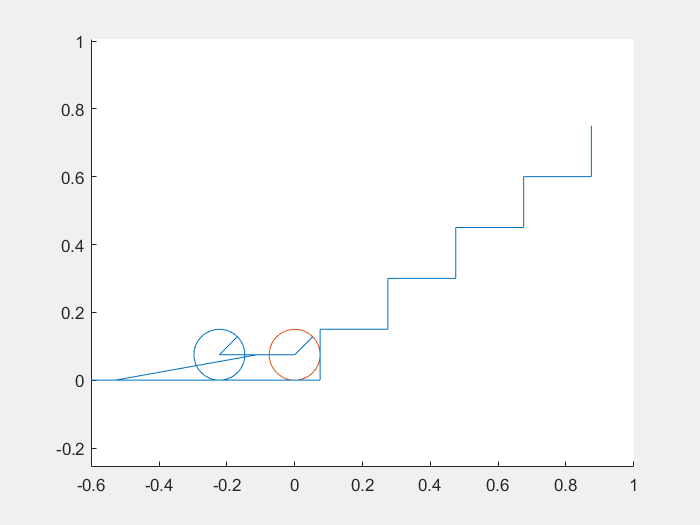

%Draw positions
drawfigure(sol1);

%Stage 3: Pulling up step with tail on ground, calculate stall torque
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_rolling; condition_wheel2NoContact;
    %Set position of front wheel
    s51 == step_pitch-0.075; s52 == rw+step_height;
    %Set vertical accelleration of bottom wheel to zero to solve for lifting torque
    a62 == 0;
    %Set the state of the device
    s62 == rw; t23 == 0;
    tv13 == 0; tv23 == 0;
    ];

sol2 = mysolver(Eqns);
sol2.T_z

$$ans = 0.57383899834159490869972912769772$$

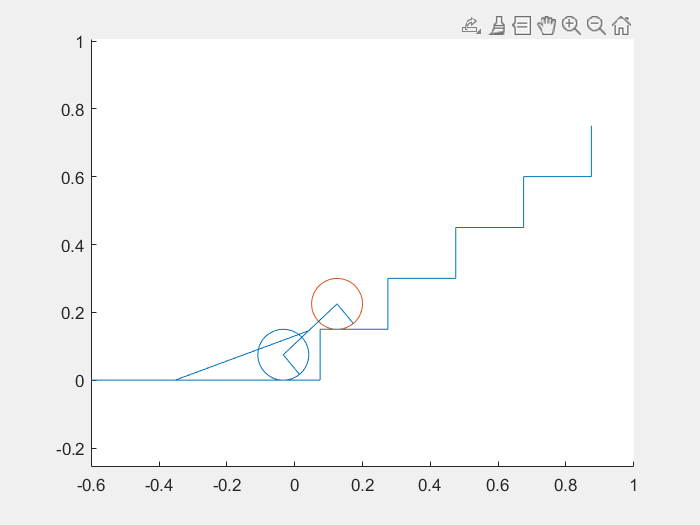

drawfigure(sol2);

%Stage 3: Pulling up step with tail on ground, calculate stall torque
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_rolling; condition_wheel2NoContact;
    %Set position of front wheel
    s51 == step_pitch-0.075; s52 == rw+step_height;
    %Set vertical accelleration of bottom wheel to zero to solve for lifting torque
    a62 == 0;
    %Set the state of the device
    t13 == 0; t23 == 0;
    tv13 == 0; tv23 == 0;
    ];

sol3 = mysolver(Eqns);
sol3.T_z

$$ans = 0.97024699693327547752853529430384$$

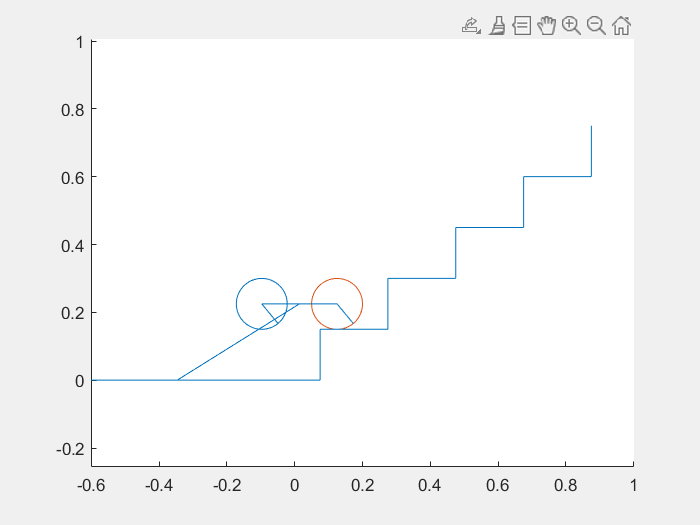

drawfigure(sol3);

%Stage 1: Lifting against step from first step with tail on ground, calculate stall torque
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_wheel1locked; condition_wheel2NoContact;
    %Set position of front wheel
    s51 == step_pitch; s52 == rw+step_height;
    %Set accellerations to zero to solve for stalling torque
    unwrap_y(a == 0)
    %Set the state of the device
    t13 == 0; t23 == 0;
    tv13 == 0; tv23 == 0;
    ];

sol3 = mysolver(Eqns);
sol3.T_z

$$ans = 0.97045043983878530066629142284365$$

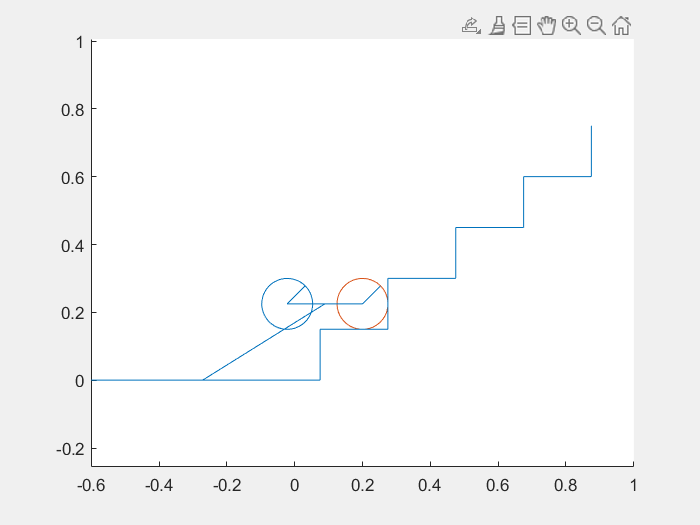

drawfigure(sol3);

%Stage 6: Pulling up step with tail on step, calculate stall torque
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnStep; condition_rolling; condition_wheel2NoContact;
    %Set position of front wheel
    s51 == 2*step_pitch-0.075; s52 == rw+2*step_height;
    %Set vertical accelleration of bottom wheel to zero to solve for lifting torque
    a62 == 0;
    %Set the state of the device
    t13 == -0.75; t23 == 0;
    tv13 == 0; tv23 == 0;
    ];

sol4 = mysolver(Eqns);
sol4.T_z

$$ans = 0.68160531804561810888897908431164$$

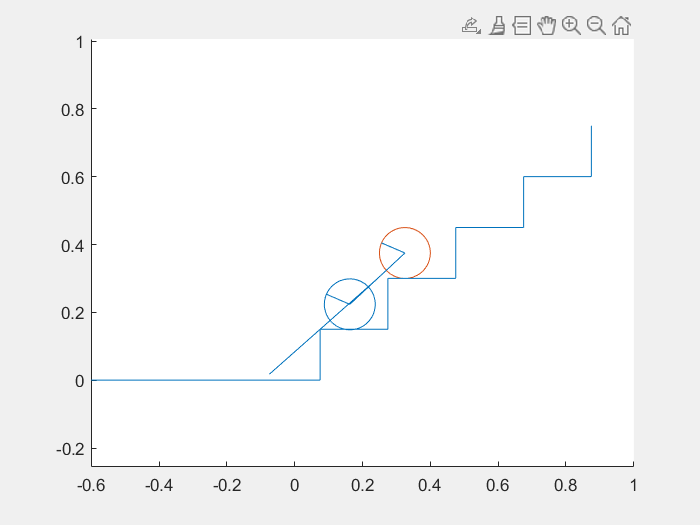

drawfigure(sol4);

%Stage 6:Pulling up step with tail on step, calculate stall torque
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnStep; condition_rolling; condition_wheel2NoContact;
    %Set position of front wheel
    s51 == 2*step_pitch-0.075; s52 == rw+2*step_height;
    %Set vertical accelleration of bottom wheel to zero to solve for lifting torque
    a62 == 0;
    %Set the state of the device
    t13 == 0; t23 == 0;
    tv13 == 0; tv23 == 0;
    ];

sol5 = mysolver(Eqns);
sol5.T_z

$$ans = 1.376845398104719578300851969928$$

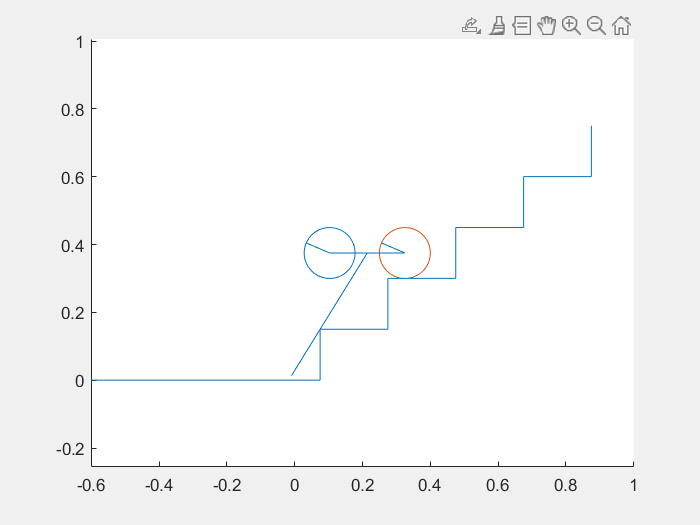

drawfigure(sol5);

%Stage 3:Lifting against step from second step with tail on first step, calculate stall torque
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnStep; condition_wheel1locked; condition_wheel2NoContact;
    %Set position of front wheel
    s51 == 2*step_pitch; s52 == rw+2*step_height;
    %Set accellerations to zero to solve for stalling torque
    unwrap_y(a == 0)
    %Set the state of the device
    t13 == 0; t23 == 0;
    tv13 == 0; tv23 == 0;
    ];
sol6 = mysolver(Eqns);
sol6.T_z

$$ans = 1.2554283227753011477576089026379$$

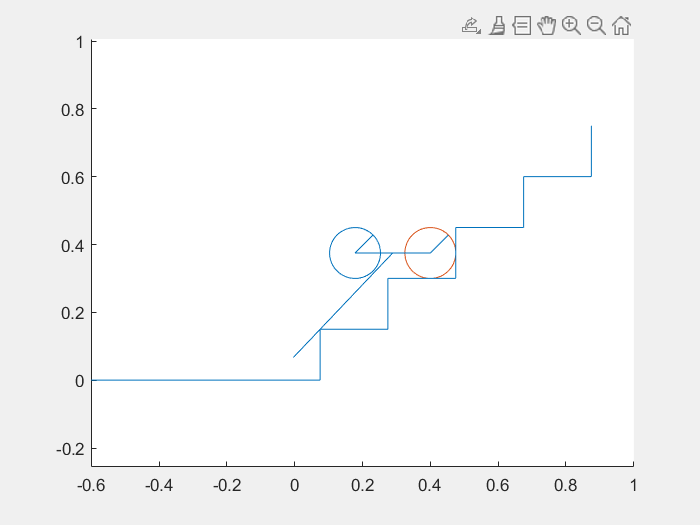

drawfigure(sol6);

%Test stall torques across stage 1 movement
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_wheel1locked; condition_wheel2NoContact;
    %Set position of front wheel
    s51 == 0; s52 == rw;
    %Set accellerations to zero to solve for stalling torque
    unwrap_y(a == 0)
    %Set the state of the device
    tv13 == 0; tv23 == 0;
    ];
[sol, unsolved] = mysolver(Eqns, 0)

sol = struct with fields:
      C_friction7: 0.0
        F_react53: 0.0
        F_react61: 0.0
        F_react62: 0.0
        F_react63: 0.0
        F_react71: 0.0
        F_react73: 0.0
               I1: 0.0015369319646590562551680125835674
               I2: 0.000068751841737150920660058550648586
               I3: 0.000013375817588925833023587828873868
               I4: 0.000013375817588925833023587828873868
               I5: 0.00012233851720283331582055097452866
               I6: 0.00012233851720283331582055097452866
               I7: 0.0032796810000000000025199842212942
        M_react61: 0.0
        M_react62: 0.0
        M_react63: 0.0
          N_idler: 33.0
         N_planet: 16.0
            N_sun: 50.0
              a11: 0.0
              a12: 0.0
              a13: 0.0
              a21: 0.0
              a22: 0.0
              a23: 0.0
              a31: 0.0
              a32: 0.0
              a33: 0.0
              a41: 0.0
              a42: 0.0
              a43: 

solutions = []


solutions =

     []



for i = linspace(0, pi/2, 100)
    solutions = [solutions; mysolver([unsolved; t13 == i; t23 == 0;], 1)];
    solutions(end).T_z
end

$$ans = 1.0137443442193619339806121273552$$

$$ans = 1.0134365780659379168849138114577$$

$$ans = 1.01293950784143331879419330377$$

$$ans = 1.012253367921846766275057280208$$

$$ans = 1.0113783773889131325421074795208$$

$$ans = 1.0103147397454628899776006065927$$

$$ans = 1.0090626425964835197374592344343$$

$$ans = 1.0076222572956657149241999057249$$

$$ans = 1.0059937385572846900037815309006$$

$$ans = 1.0041772240333364891709302364911$$

$$ans = 1.0021728338559209863768083952309$$

$$ans = 0.99998067014493750939314027750514$$

$$ans = 0.99760081648123592225700375463949$$

$$ans = 0.99503333734544578978571908804979$$

$$ans = 0.99227827752278915140006002634759$$

$$ans = 0.98933566147426867712978906677257$$

$$ans = 0.98620549267471279455811653877462$$

$$ans = 0.98288775291825298917324040246473$$

$$ans = 0.97938240159190611820512544730518$$

$$ans = 0.97568937491803646307005459910612$$

$$ans = 0.9718085851665785979147703732385$$

$$ans = 0.96773991983801318648385113585194$$

$$ans = 0.96348324081820374550536120350262$$

$$ans = 0.95903838350632343130519462465316$$

$$ans = 0.9544051559172272096316861517709$$

$$ans = 0.94958333775975653818689537574252$$

$$ans = 0.94457267949260109613842619543436$$

$$ans = 0.93937290135948528961487287700038$$

$$ans = 0.93398369240559638525061208131685$$

$$ans = 0.9284047094773262952209174710647$$

$$ans = 0.92263557620756035626180999110363$$

$$ans = 0.91667588198891398832667881453098$$

$$ans = 0.91052518093749193684256694545958$$

$$ans = 0.90418299084992491912059685990224$$

$$ans = 0.89764879215662490290718424129396$$

$$ans = 0.89092202687439290258750185139575$$

$$ans = 0.88400209756171200928889469816527$$

$$ans = 0.87688836628026325916506016174613$$

$$ans = 0.86958015356641273156163658083997$$

$$ans = 0.86207673741663475265445948753045$$

$$ans = 0.85437735229105800954959758196521$$

$$ans = 0.84648118813954845267290561671243$$

$$ans = 0.83838738945497472433831181231176$$

$$ans = 0.830095054358538085279490904573$$

$$ans = 0.82160323372228894513277846860674$$

$$ans = 0.81291093033419560081983966645164$$

$$ans = 0.80401709811137704614293179857603$$

$$ans = 0.79492064136736006587442323825353$$

$$ans = 0.78562041413947052647802450572921$$

$$ans = 0.77611521958271900843509981329522$$

$$ans = 0.76640380943679080183466507194476$$

$$ans = 0.75648488357299884030265176529794$$

$$ans = 0.74635708962830433293548420254421$$

$$ans = 0.73601902273375254455395571163083$$

$$ans = 0.72546922534490916591448282502908$$

$$ans = 0.71470618718211472152428871824652$$

$$ans = 0.70372834528859911697696245029136$$

$$ans = 0.69253408421471428401488386138037$$

$$ans = 0.68112173633674841493971938443405$$

$$ans = 0.66948958231897888669307827661338$$

$$ans = 0.6576358517278009824316215474295$$

$$ans = 0.6455587238069341765010769555608$$

$$ans = 0.63325632842285524095225606721326$$

$$ans = 0.62072674718973587772036390167055$$

$$ans = 0.60796801478327004075481189068672$$

$$ans = 0.59497812045286059360327251395475$$

$$ans = 0.5817550097416944097334535120478$$

$$ans = 0.56829658642426738430506540370943$$

$$ans = 0.55460071467092397345062416687121$$

$$ans = 0.54066522144894767212059742633127$$

$$ans = 0.52648789916967713033926116302168$$

$$ans = 0.51206650859102523043978378572234$$

$$ans = 0.49739878198464324883044256358609$$

$$ans = 0.48248242657679706439335399371156$$

$$ans = 0.4673151282718051373426797511867$$

$$ans = 0.45189455566662659102439459077921$$

$$ans = 0.43621836436488015892358494991155$$

$$ans = 0.42028420159821904742206674892719$$

$$ans = 0.40408971116258102523416322111457$$

$$ans = 0.3876325386763754862094552150287$$

$$ans = 0.37091033716715814991170856231749$$

$$ans = 0.35392077299277788783456136546564$$

$$ans = 0.33666153210235744728478960964031$$

$$ans = 0.31913032664178929018994033908469$$

$$ans = 0.30132490190768823024243042296404$$

$$ans = 0.28324304365294307248328927000456$$

$$ans = 0.2648825857461492561561634284538$$

$$ans = 0.24624141818628299790809611260239$$

$$ans = 0.22731749547299426762012701344087$$

$$ans = 0.20810884533185097255978667999606$$

$$ans = 0.18861357779276008987566284392046$$

$$ans = 0.16882989461862354238207669205593$$

$$ans = 0.14875609908005799804101442777241$$

$$ans = 0.12839060607071941279150872235017$$

$$ans = 0.10773195255642624882057578021562$$

$$ans = 0.086778808349871414201668669863937$$

$$ans = 0.065529987201253934362789649566071$$

$$ans = 0.043984458193649363633565046053025$$

$$ans = 0.022141357430375503763539972618005$$

$$ans = -2.2549040588807403099144519112892e-40$$

solutions(:).F_react72

$$ans = 4.5371486278176270836585006866205$$

$$ans = 4.5382649955031740247958691266267$$

$$ans = 4.5389739044830321335860744325133$$

$$ans = 4.5392745723566787647509628889824$$

$$ans = 4.5391660908543293646918795657792$$

$$ans = 4.5386474252200222466756797864784$$

$$ans = 4.5377174136196892442916805903362$$

$$ans = 4.5363747665754676390137668791056$$

$$ans = 4.5346180664276953305825564100549$$

$$ans = 4.5324457668262217551900350771638$$

$$ans = 4.5298561922528616253418783427642$$

$$ans = 4.5268475375770172244812272437316$$

$$ans = 4.5234178676466977835010548289037$$

$$ans = 4.5195651169173714248063301210377$$

$$ans = 4.5152870891212962956455858452986$$

$$ans = 4.5105814569801928206009487903686$$

$$ans = 4.5054457619643384576582569482908$$

$$ans = 4.4998774141013898951441984377577$$

$$ans = 4.4938736918384652056988538252317$$

$$ans = 4.4874317419612499796916720104743$$

$$ans = 4.4805485795741267669868664591831$$

$$ans = 4.4732210881455661050391252142079$$

$$ans = 4.4654460196232598125189097250742$$

$$ans = 4.4572199946237228556498823067123$$

$$ans = 4.4485395027013386866600242034647$$

$$ans = 4.4394009027020742083163845439578$$

$$ans = 4.4298004232073440919916777139179$$

$$ans = 4.4197341630737596819352848450657$$

$$ans = 4.409198092074754722371235455175$$

$$ans = 4.3981880516503381657674483609527$$

$$ans = 4.3866997557714828292213741892718$$

$$ans = 4.3747287919259170786416722282905$$

$$ans = 4.3622706222323444008703765682113$$

$$ans = 4.3493205846903719803494055262434$$

$$ans = 4.3358738945736834807976077779567$$

$$ans = 4.321925645974242336832148307575$$

$$ans = 4.3074708135055591193829523063845$$

$$ans = 4.2925042541732990256575902932814$$

$$ans = 4.2770207094217422718742579141349$$

$$ans = 4.2610148073648400861343027619516$$

$$ans = 4.2444810652108309992405346620545$$

$$ans = 4.2274138918895950411892446844597$$

$$ans = 4.2098075908921260378031109880275$$

$$ans = 4.1916563633316931728447964953664$$

$$ans = 4.1729543112364409844919138132166$$

$$ans = 4.1536954410833405926420783118047$$

$$ans = 4.1338736675835527414065564045436$$

$$ans = 4.1134828177293936729238806671898$$

$$ans = 4.0925166351132063580697247733082$$

$$ans = 4.0709687845285305840705082866043$$

$$ans = 4.048832856864034183042815885133$$

$$ans = 4.026102374300712585156524826292$$

$$ans = 4.0027707958228831676478470903073$$

$$ans = 3.9788315230534927896537499920897$$

$$ans = 3.9542779064242196728118892082944$$

$$ans = 3.9291032516907826112950435384116$$

$$ans = 3.9033008268037695637061991711498$$

$$ans = 3.8768638691451621796718766112677$$

$$ans = 3.8497855931405609349010414391537$$

$$ans = 3.8220591982569054882086760262441$$

$$ans = 3.7936778773952348476550786912304$$

$$ans = 3.7646348256877401800854266359107$$

$$ans = 3.7349232497080278907282609182822$$

$$ans = 3.7045363771031302489357396777275$$

$$ans = 3.6734674666553737023810904676771$$

$$ans = 3.6417098187817395206702573307104$$

$$ans = 3.6092567864778260196546092671764$$

$$ans = 3.5761017867129448904372434179259$$

$$ans = 3.542238312282254721817109121946$$

$$ans = 3.5076599441211513777415128766147$$

$$ans = 3.4723603640863962817631207685986$$

$$ans = 3.4363333682076687784095747295818$$

$$ans = 3.3995728804123766035926442692179$$

$$ans = 3.362072966725648232720902581104$$

$$ans = 3.3238278499464617351769253264373$$

$$ans = 3.284831924799836121174147852501$$

$$ans = 3.2450797735639225257011435706681$$

$$ans = 3.2045661821696835734201446755237$$

$$ans = 3.163286156769639687126887610584$$

$$ans = 3.1212349407708908644783088889809$$

$$ans = 3.0784080323262916261795445953066$$

$$ans = 3.0348012022762656605473449710432$$

$$ans = 2.9904105125322955396941523909456$$

$$ans = 2.945232334891612310257704412318$$

$$ans = 2.8992633702710404839981206751458$$

$$ans = 2.8525006683463268623605799341906$$

$$ans = 2.8049416475815977965190471381498$$

$$ans = 2.756584115631850170396490908943$$

$$ans = 2.7074262900995880542504528697409$$

$$ans = 2.6574668196248712708307060671311$$

$$ans = 2.6067048052861459199668399020967$$

$$ans = 2.5551398222872823223167730964541$$

$$ans = 2.5027719419042552100241722290733$$

$$ans = 2.4496017536628669064806619219301$$

$$ans = 2.3956303877168395650199819590441$$

$$ans = 2.3408595373934904314329034891923$$

$$ans = 2.2852914818720580202152254387989$$

$$ans = 2.2289291089575708418086218283421$$

$$ans = 2.171775937910948033216592119498$$

$$ans = 2.1138361422937974506974789790092$$

Create an animation by using the Runge Kutta method for discrete ODE solution

%Motor torque is not constant, create function to determine motor torque
%based on speed and voltage
motor_stallTorque = 6; % Nm
motor_NLSpeed = 0.6; %rad/s
syms speed stallTorque voltage 
eqns_motor = [
    speed == tv23;
    T_z == 2*motor_stallTorque*(voltage/12.0-speed/motor_NLSpeed)
    stallTorque == motor_stallTorque*(voltage/12.0)]

$$eqns\_motor = \left(\begin{array}{c} \mathrm{speed}={\mathrm{tv}}_{23}\\ T_{z}=\mathrm{voltage}-20\,\mathrm{speed}\\ \mathrm{stallTorque}=\frac{\mathrm{voltage}}{2} \end{array}\right)$$


%Incomplete solution for movement1
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_wheel1locked; condition_wheel2NoContact; eqns_motor;
    %Set position of front wheel
    s51 == 0; s52 == rw;
    %Set Motor voltage 
    stallTorque == 6;
    ];

[sol, unsolved] = mysolver(Eqns, 0);

Eqns=[unsolved;
    t13 == 0; t23 ==0 
    tv13 == 0; tv23 == 0;
    ]; 
[sol2, unsolved2] = mysolver(Eqns, 1, sol)

sol2 = struct with fields:
      C_friction7: 0.0
        F_react51: -2.1688637752568830846526917944204
        F_react52: 52.974073073598547649308023881396
        F_react53: 0.0
        F_react61: 0.0
        F_react62: 0.0
        F_react63: 0.0
        F_react71: 0.0
        F_react72: 31.851481536324924636656427252479
        F_react73: 0.0
               I1: 0.0015369319646590562551680125835674
               I2: 0.000068751841737150920660058550648586
               I3: 0.000013375817588925833023587828873868
               I4: 0.000013375817588925833023587828873868
               I5: 0.00012233851720283331582055097452866
               I6: 0.00012233851720283331582055097452866
               I7: 0.0032796810000000000025199842212942
        M_react53: -3.8119786171104015771491192151548
        M_react61: 0.0
        M_react62: 0.0
        M_react63: 0.0
          N_idler: 33.0
         N_planet: 16.0
            N_sun: 50.0
              T_z: 12.0
              a11: 0.0
          


unsolved2 =

     []



%Start calculations
framesol = []


framesol =

     []



frameeqs = unsolved

Step_Value = 0.005;
t_beg = 0;
t_end = 10;
t_intial=0;
u_intial=[sol2.t13,sol2.t23,sol2.tv13,sol2.tv23];
% Routine starts here
h=Step_Value;
t=t_beg:h:t_end;
u=zeros(4,length(t));
u(:,1)=u_intial;




for i=1:(length(t)-1)
    t0=t(i);
    up1=u(1,i); %t13
    up2=u(2,i); %t23
    up3=u(3,i); %tv13
    up4=u(4,i); %tv23
    framesol = [framesol; mysolver([unsolved; t13 == up1; t23 == up2; tv13 == up3; tv23 == up4;], 1)];
    k1 = [framesol(i).tv13; framesol(i).tv23; framesol(i).ta13; framesol(i).ta23];
    tempsol = mysolver([unsolved; t13 == up1+0.5*h*k1(1); t23 == up2+0.5*h*k1(2); tv13 == up3+0.5*h*k1(3); tv23 == up4+0.5*h*k1(4);], 1);
    k2 = [tempsol.tv13; tempsol.tv23; tempsol.ta13; tempsol.ta23];
    tempsol = mysolver([unsolved; t13 == up1+0.5*h*k2(1); t23 == up2+0.5*h*k2(2); tv13 == up3+0.5*h*k2(3); tv23 == up4+0.5*h*k2(4);], 1);
    k3 = [tempsol.tv13; tempsol.tv23; tempsol.ta13; tempsol.ta23];
    tempsol = mysolver([unsolved; t13 == up1+k3(1)*h; t23 == up2+k3(2)*h; tv13 == up3+k3(3)*h; tv23 == up4+k3(4)*h], 1);
    k4 = [tempsol.tv13; tempsol.tv23; tempsol.ta13; tempsol.ta23];
    u(:,i+1) = u(:,i) + (h/6)*(k1+2*k2+2*k3+k4);
    i
end

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

i = 28

i = 29

i = 30

i = 31

i = 32

i = 33

i = 34

i = 35

i = 36

i = 37

i = 38

i = 39

i = 40

i = 41

i = 42

i = 43

i = 44

i = 45

i = 46

i = 47

i = 48

i = 49

i = 50

i = 51

i = 52

i = 53

i = 54

i = 55

i = 56

i = 57

i = 58

i = 59

i = 60

i = 61

i = 62

i = 63

i = 64

i = 65

i = 66

i = 67

i = 68

i = 69

i = 70

i = 71

i = 72

i = 73

i = 74

i = 75

i = 76

i = 77

i = 78

i = 79

i = 80

i = 81

i = 82

i = 83

i = 84

i = 85

i = 86

i = 87

i = 88

i = 89

i = 90

i = 91

i = 92

i = 93

i = 94

i = 95

i = 96

i = 97

i = 98

i = 99

i = 100

i = 101

i = 102

i = 103

i = 104

i = 105

i = 106

i = 107

i = 108

i = 109

i = 110

i = 111

i = 112

i = 113

i = 114

i = 115

i = 116

i = 117

i = 118

i = 119

i = 120

i = 121

i = 122

i = 123

i = 124

i = 125

i = 126

i = 127

i = 128

i = 129

i = 130

i = 131

i = 132

i = 133

i = 134

i = 135

i = 136

i = 137

i = 138

i = 139

i = 140

i = 141

i = 142

i = 143

i = 144

i = 145

i = 146

i = 147

i = 148

i = 149

i = 150

i = 151

i = 152

i = 153

i = 154

i = 155

i = 156

i = 157

i = 158

i = 159

i = 160

i = 161

i = 162

i = 163

i = 164

i = 165

i = 166

i = 167

i = 168

i = 169

i = 170

i = 171

i = 172

i = 173

i = 174

i = 175

i = 176

i = 177

i = 178

i = 179

i = 180

i = 181

i = 182

i = 183

i = 184

i = 185

i = 186

i = 187

i = 188

i = 189

i = 190

i = 191

i = 192

i = 193

i = 194

i = 195

i = 196

i = 197

i = 198

i = 199

i = 200

i = 201

i = 202

i = 203

i = 204

i = 205

i = 206

i = 207

i = 208

i = 209

i = 210

i = 211

i = 212

i = 213

i = 214

i = 215

i = 216

i = 217

i = 218

i = 219

i = 220

i = 221

i = 222

i = 223

i = 224

i = 225

i = 226

i = 227

i = 228

i = 229

i = 230

i = 231

i = 232

i = 233

i = 234

i = 235

i = 236

i = 237

i = 238

i = 239

i = 240

i = 241

i = 242

i = 243

i = 244

i = 245

i = 246

i = 247

i = 248

i = 249

i = 250

i = 251

i = 252

i = 253

i = 254

i = 255

i = 256

i = 257

i = 258

i = 259

i = 260

i = 261

i = 262

i = 263

i = 264

i = 265

i = 266

i = 267

i = 268

i = 269

i = 270

i = 271

i = 272

i = 273

i = 274

i = 275

i = 276

i = 277

i = 278

i = 279

i = 280

i = 281

i = 282

i = 283

i = 284

i = 285

i = 286

i = 287

i = 288

i = 289

i = 290

i = 291

i = 292

i = 293

i = 294

i = 295

i = 296

i = 297

i = 298

i = 299

i = 300

i = 301

i = 302

i = 303

i = 304

i = 305

i = 306

i = 307

i = 308

i = 309

i = 310

i = 311

i = 312

i = 313

i = 314

i = 315

i = 316

i = 317

i = 318

i = 319

i = 320

i = 321

i = 322

i = 323

i = 324

i = 325

i = 326

i = 327

i = 328

i = 329

i = 330

i = 331

i = 332

i = 333

i = 334

i = 335

i = 336

i = 337

i = 338

i = 339

i = 340

i = 341

i = 342

i = 343

i = 344

i = 345

i = 346

i = 347

i = 348

i = 349

i = 350

i = 351

i = 352

i = 353

i = 354

i = 355

i = 356

i = 357

i = 358

i = 359

i = 360

i = 361

i = 362

i = 363

i = 364

i = 365

i = 366

i = 367

i = 368

i = 369

i = 370

i = 371

i = 372

i = 373

i = 374

i = 375

i = 376

i = 377

i = 378

i = 379

i = 380

i = 381

i = 382

i = 383

i = 384

i = 385

i = 386

i = 387

i = 388

i = 389

i = 390

i = 391

i = 392

i = 393

i = 394

i = 395

i = 396

i = 397

i = 398

i = 399

i = 400

i = 401

i = 402

i = 403

i = 404

i = 405

i = 406

i = 407

i = 408

i = 409

i = 410

i = 411

i = 412

i = 413

i = 414

i = 415

i = 416

i = 417

i = 418

i = 419

i = 420

i = 421

i = 422

i = 423

i = 424

i = 425

i = 426

i = 427

i = 428

i = 429

i = 430

i = 431

i = 432

i = 433

i = 434

i = 435

i = 436

i = 437

i = 438

i = 439

i = 440

i = 441

i = 442

i = 443

i = 444

i = 445

i = 446

i = 447

i = 448

i = 449

i = 450

i = 451

i = 452

i = 453

i = 454

i = 455

i = 456

i = 457

i = 458

i = 459

i = 460

i = 461

i = 462

i = 463

i = 464

i = 465

i = 466

i = 467

i = 468

i = 469

i = 470

i = 471

i = 472

i = 473

i = 474

i = 475

i = 476

i = 477

i = 478

i = 479

i = 480

i = 481

i = 482

i = 483

i = 484

i = 485

i = 486

i = 487

i = 488

i = 489

i = 490

i = 491

i = 492

i = 493

i = 494

i = 495

i = 496

i = 497

i = 498

i = 499

i = 500

i = 501

i = 502

i = 503

i = 504

i = 505

i = 506

i = 507

i = 508

i = 509

i = 510

i = 511

i = 512

i = 513

i = 514

i = 515

i = 516

i = 517

i = 518

i = 519

i = 520

i = 521

i = 522

i = 523

i = 524

i = 525

i = 526

i = 527

i = 528

i = 529

i = 530

i = 531

i = 532

i = 533

i = 534

i = 535

i = 536

i = 537

i = 538

i = 539

i = 540

i = 541

i = 542

i = 543

i = 544

i = 545

i = 546

i = 547

i = 548

i = 549

i = 550

i = 551

i = 552

i = 553

i = 554

i = 555

i = 556

i = 557

i = 558

i = 559

i = 560

i = 561

i = 562

i = 563

i = 564

i = 565

i = 566

i = 567

i = 568

i = 569

i = 570

i = 571

i = 572

i = 573

i = 574

i = 575

i = 576

i = 577

i = 578

i = 579

i = 580

i = 581

i = 582

i = 583

i = 584

i = 585

i = 586

i = 587

i = 588

i = 589

i = 590

i = 591

i = 592

i = 593

i = 594

i = 595

i = 596

i = 597

i = 598

i = 599

i = 600

i = 601

i = 602

i = 603

i = 604

i = 605

i = 606

i = 607

i = 608

i = 609

i = 610

i = 611

i = 612

i = 613

i = 614

i = 615

i = 616

i = 617

i = 618

i = 619

i = 620

i = 621

i = 622

i = 623

i = 624

i = 625

i = 626

i = 627

i = 628

i = 629

i = 630

i = 631

i = 632

i = 633

i = 634

i = 635

i = 636

i = 637

i = 638

i = 639

i = 640

i = 641

i = 642

i = 643

i = 644

i = 645

i = 646

i = 647

i = 648

i = 649

i = 650

i = 651

i = 652

i = 653

i = 654

i = 655

i = 656

i = 657

i = 658

i = 659

i = 660

i = 661

i = 662

i = 663

i = 664

i = 665

i = 666

i = 667

i = 668

i = 669

i = 670

i = 671

i = 672

i = 673

i = 674

i = 675

i = 676

i = 677

i = 678

i = 679

i = 680

i = 681

i = 682

i = 683

i = 684

i = 685

i = 686

i = 687

i = 688

i = 689

i = 690

i = 691

i = 692

i = 693

i = 694

i = 695

i = 696

i = 697

i = 698

i = 699

i = 700

i = 701

i = 702

i = 703

i = 704

i = 705

i = 706

i = 707

i = 708

i = 709

i = 710

i = 711

i = 712

i = 713

i = 714

i = 715

i = 716

i = 717

i = 718

i = 719

i = 720

i = 721

i = 722

i = 723

i = 724

i = 725

i = 726

i = 727

i = 728

i = 729

i = 730

i = 731

i = 732

i = 733

i = 734

i = 735

i = 736

i = 737

i = 738

i = 739

i = 740

i = 741

i = 742

i = 743

i = 744

i = 745

i = 746

i = 747

i = 748

i = 749

i = 750

i = 751

i = 752

i = 753

i = 754

i = 755

i = 756

i = 757

i = 758

i = 759

i = 760

i = 761

i = 762

i = 763

i = 764

i = 765

i = 766

i = 767

i = 768

i = 769

i = 770

i = 771

i = 772

i = 773

i = 774

i = 775

i = 776

i = 777

i = 778

i = 779

i = 780

i = 781

i = 782

i = 783

i = 784

i = 785

i = 786

i = 787

i = 788

i = 789

i = 790

i = 791

i = 792

i = 793

i = 794

i = 795

i = 796

i = 797

i = 798

i = 799

i = 800

i = 801

i = 802

i = 803

i = 804

i = 805

i = 806

i = 807

i = 808

i = 809

i = 810

i = 811

i = 812

i = 813

i = 814

i = 815

i = 816

i = 817

i = 818

i = 819

i = 820

i = 821

i = 822

i = 823

i = 824

i = 825

i = 826

i = 827

i = 828

i = 829

i = 830

i = 831

i = 832

i = 833

i = 834

i = 835

i = 836

i = 837

i = 838

i = 839

i = 840

i = 841

i = 842

i = 843

i = 844

i = 845

i = 846

i = 847

i = 848

i = 849

i = 850

i = 851

i = 852

i = 853

i = 854

i = 855

i = 856

i = 857

i = 858

i = 859

i = 860

i = 861

i = 862

i = 863

i = 864

i = 865

i = 866

i = 867

i = 868

i = 869

i = 870

i = 871

i = 872

i = 873

i = 874

i = 875

i = 876

i = 877

i = 878

i = 879

i = 880

i = 881

i = 882

i = 883

i = 884

i = 885

i = 886

i = 887

i = 888

i = 889

i = 890

i = 891

i = 892

i = 893

i = 894

i = 895

i = 896

i = 897

i = 898

i = 899

i = 900

i = 901

i = 902

i = 903

i = 904

i = 905

i = 906

i = 907

i = 908

i = 909

i = 910

i = 911

i = 912

i = 913

i = 914

i = 915

i = 916

i = 917

i = 918

i = 919

i = 920

i = 921

i = 922

i = 923

i = 924

i = 925

i = 926

i = 927

i = 928

i = 929

i = 930

i = 931

i = 932

i = 933

i = 934

i = 935

i = 936

i = 937

i = 938

i = 939

i = 940

i = 941

i = 942

i = 943

i = 944

i = 945

i = 946

i = 947

i = 948

i = 949

i = 950

i = 951

i = 952

i = 953

i = 954

i = 955

i = 956

i = 957

i = 958

i = 959

i = 960

i = 961

i = 962

i = 963

i = 964

i = 965

i = 966

i = 967

i = 968

i = 969

i = 970

i = 971

i = 972

i = 973

i = 974

i = 975

i = 976

i = 977

i = 978

i = 979

i = 980

i = 981

i = 982

i = 983

i = 984

i = 985

i = 986

i = 987

i = 988

i = 989

i = 990

i = 991

i = 992

i = 993

i = 994

i = 995

i = 996

i = 997

i = 998

i = 999

i = 1000

i = 1001

i = 1002

i = 1003

i = 1004

i = 1005

i = 1006

i = 1007

i = 1008

i = 1009

i = 1010

i = 1011

i = 1012

i = 1013

i = 1014

i = 1015

i = 1016

i = 1017

i = 1018

i = 1019

i = 1020

i = 1021

i = 1022

i = 1023

i = 1024

i = 1025

i = 1026

i = 1027

i = 1028

i = 1029

i = 1030

i = 1031

i = 1032

i = 1033

i = 1034

i = 1035

i = 1036

i = 1037

i = 1038

i = 1039

i = 1040

i = 1041

i = 1042

i = 1043

i = 1044

i = 1045

i = 1046

i = 1047

i = 1048

i = 1049

i = 1050

i = 1051

i = 1052

i = 1053

i = 1054

i = 1055

i = 1056

i = 1057

i = 1058

i = 1059

i = 1060

i = 1061

i = 1062

i = 1063

i = 1064

i = 1065

i = 1066

i = 1067

i = 1068

i = 1069

i = 1070

i = 1071

i = 1072

i = 1073

i = 1074

i = 1075

i = 1076

i = 1077

i = 1078

i = 1079

i = 1080

i = 1081

i = 1082

i = 1083

i = 1084

i = 1085

i = 1086

i = 1087

i = 1088

i = 1089

i = 1090

i = 1091

i = 1092

i = 1093

i = 1094

i = 1095

i = 1096

i = 1097

i = 1098

i = 1099

i = 1100

i = 1101

i = 1102

i = 1103

i = 1104

i = 1105

i = 1106

i = 1107

i = 1108

i = 1109

i = 1110

i = 1111

i = 1112

i = 1113

i = 1114

i = 1115

i = 1116

i = 1117

i = 1118

i = 1119

i = 1120

i = 1121

i = 1122

i = 1123

i = 1124

i = 1125

i = 1126

i = 1127

i = 1128

i = 1129

i = 1130

i = 1131

i = 1132

i = 1133

i = 1134

i = 1135

i = 1136

i = 1137

i = 1138

i = 1139

i = 1140

i = 1141

i = 1142

i = 1143

i = 1144

i = 1145

i = 1146

i = 1147

i = 1148

i = 1149

i = 1150

i = 1151

i = 1152

i = 1153

i = 1154

i = 1155

i = 1156

i = 1157

i = 1158

i = 1159

i = 1160

i = 1161

i = 1162

i = 1163

i = 1164

i = 1165

i = 1166

i = 1167

i = 1168

i = 1169

i = 1170

i = 1171

i = 1172

i = 1173

i = 1174

i = 1175

i = 1176

i = 1177

i = 1178

i = 1179

i = 1180

i = 1181

i = 1182

i = 1183

i = 1184

i = 1185

i = 1186

i = 1187

i = 1188

i = 1189

i = 1190

i = 1191

i = 1192

i = 1193

i = 1194

i = 1195

i = 1196

i = 1197

i = 1198

i = 1199

i = 1200

i = 1201

i = 1202

i = 1203

i = 1204

i = 1205

f = fieldnames(sol)

f = 172×1 cell array
    {'C_friction7'}
    {'F_react53'  }
    {'F_react61'  }
    {'F_react62'  }
    {'F_react63'  }
    {'F_react71'  }
    {'F_react73'  }
    {'I1'         }
    {'I2'         }
    {'I3'         }
    {'I4'         }
    {'I5'         }
    {'I6'         }
    {'I7'         }
    {'M_react61'  }
    {'M_react62'  }
    {'M_react63'  }
    {'N_idler'    }
    {'N_planet'   }
    {'N_sun'      }
    {'a13'        }
    {'a23'        }
    {'a33'        }
    {'a43'        }
    {'a51'        }
    {'a52'        }
    {'a53'        }
    {'a63'        }
    {'a73'        }
    {'f23'        }


nframes = length(framesol)

nframes = 1206

for i = 1:length(f)
    for j = 1:nframes
        framesol(j).(f{i}) = sol.(f{i});
    end
end

F(length(framesol)) = struct('cdata',[],'colormap',[]);
for j=1:length(framesol)
    f=figure('visible','off');
    hold on;
    %wheels
    circle(framesol(j).s61, framesol(j).s62, framesol(j).rw);
    line([framesol(j).s61,framesol(j).s61+framesol(j).rw*cos(-framesol(j).t63+pi/4)],[framesol(j).s62,framesol(j).s62+framesol(j).rw*sin(-framesol(j).t63+pi/4)])
    
    circle(framesol(j).s51, framesol(j).s52, framesol(j).rw);
    line([framesol(j).s51,framesol(j).s51+framesol(j).rw*cos(-framesol(j).t53+pi/4)],[framesol(j).s52,framesol(j).s52+framesol(j).rw*sin(-framesol(j).t53+pi/4)])
    
    %frame
    line([framesol(j).s51,framesol(j).s61],[framesol(j).s52,framesol(j).s62])
    
    %Tail
    line([framesol(j).s11,framesol(j).s7End1],[framesol(j).s12,framesol(j).s7End2])
    
    axis equal;
    xlim([-0.6,1])
    %ylim([-0.1, 0.5])
    %step
    corner(:,1) = [framesol(j).step_start1-10; framesol(j).step_start2];
    for i= 1:5
        corner(:,2*i) =  [framesol(j).step_start1+framesol(j).step_pitch*(i-1); framesol(j).step_start2+framesol(j).step_height*(i-1)];
        corner(:,2*i+1) =  [framesol(j).step_start1+framesol(j).step_pitch*(i-1); framesol(j).step_start2+framesol(j).step_height*(i)];
    end
    line(corner(1,:), corner(2,:))
    hold off;
    F(j) = getframe(gcf);
end

fig = figure;


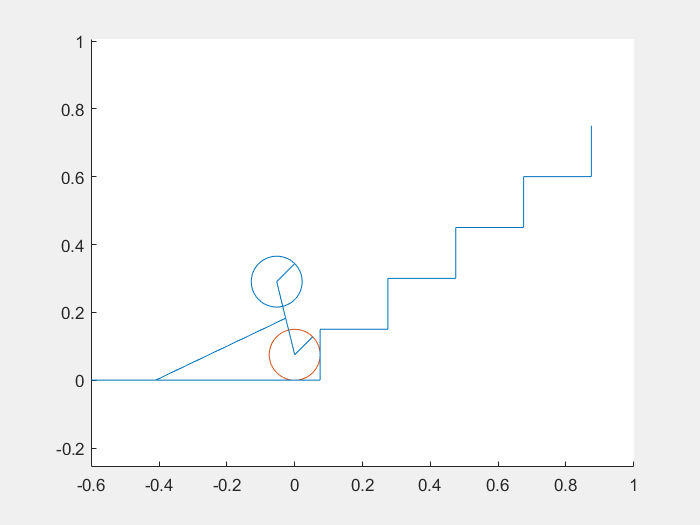


movie(fig, F, 1, 1/h);



f=figure('visible','on');
hold on;
%wheels
circle(sol.s61, sol.s62, sol.rw);
line([sol.s61,sol.s61+sol.rw*cos(-sol.t63+pi/4)],[sol.s62,sol.s62+sol.rw*sin(-sol.t63+pi/4)])

circle(sol.s51, sol.s52, sol.rw);
line([sol.s51,sol.s51+sol.rw*cos(-sol.t53+pi/4)],[sol.s52,sol.s52+sol.rw*sin(-sol.t53+pi/4)])

%frame
line([sol.s51,sol.s61],[sol.s52,sol.s62])

%Tail
line([sol.s11,sol.s7End1],[sol.s12,sol.s7End2])

axis equal;
xlim([-0.6,1])
%ylim([-0.1, 0.5])
%step
corner(:,1) = [sol.step_start1-10; sol.step_start2];
for i= 1:5
    corner(:,2*i) =  [sol.step_start1+sol.step_pitch*(i-1); sol.step_start2+sol.step_height*(i-1)];
    corner(:,2*i+1) =  [sol.step_start1+sol.step_pitch*(i-1); sol.step_start2+sol.step_height*(i)];
end
line(corner(1,:), corner(2,:))
% line([sol.step_start1-10, sol.step_start1], [sol.step_start2,sol.step_start2])
% line([sol.step_start1, sol.step_start1], [sol.step_start2, sol.step_start2+ sol.step_height])
% line([sol.step_start1, sol.step_start1+sol.step_pitch], [sol.step_height, sol.step_height])
hold off;



function f = drawfigure(sol)
    f=figure('visible','on');
    hold on;
    %wheels
    circle(sol.s61, sol.s62, sol.rw);
    line([sol.s61,sol.s61+sol.rw*cos(-sol.t63+pi/4)],[sol.s62,sol.s62+sol.rw*sin(-sol.t63+pi/4)])
    
    circle(sol.s51, sol.s52, sol.rw);
    line([sol.s51,sol.s51+sol.rw*cos(-sol.t53+pi/4)],[sol.s52,sol.s52+sol.rw*sin(-sol.t53+pi/4)])
    
    %frame
    line([sol.s51,sol.s61],[sol.s52,sol.s62])
    
    %Tail
    line([sol.s11,sol.s7End1],[sol.s12,sol.s7End2])
    
    axis equal;
    xlim([-0.6,1])
    %ylim([-0.1, 0.5])
    %step
    corner(:,1) = [sol.step_start1-10; sol.step_start2];
    for i= 1:5
        corner(:,2*i) =  [sol.step_start1+sol.step_pitch*(i-1); sol.step_start2+sol.step_height*(i-1)];
        corner(:,2*i+1) =  [sol.step_start1+sol.step_pitch*(i-1); sol.step_start2+sol.step_height*(i)];
    end
    line(corner(1,:), corner(2,:))
    hold off;
end

function h = circle(x,y,r)
th = 0:pi/50:2*pi;
xunit = r * cos(th) + x;
yunit = r * sin(th) + y;
h = plot(xunit, yunit);
end